# `Demo_00:`    Steady State Heat Transfer Analysis **- Finite Difference**

 **ATTENTION: ** This is a **simplified version** of the more "flexible" solution shown in [`DEMO_01_bh_2D_thermal_design_using_Finite_Diff.mlx`](matlab:  edit('DEMO_01_bh_2D_thermal_design_using_Finite_Diff.mlx');).  It is simplified because:

-  We start with an EXCEL file that defines the NODE geometry and the NODE type.

- The NODE geometry corresponds to the specific case of $\Delta x\;=\;\Delta y=0\ldotp 003\;\;\left(m\right)\;$

- The assembly AND solution of the GLOBAL $A\;\textrm{and}\;b$ matrices is done directly in the script ... so you can SEE what's happening !

In this example we'll perform a **Steady State Thermal analysis** of a roof cavity insulation system typically found in residential houses.  The scenario that we'll consider is shown below:

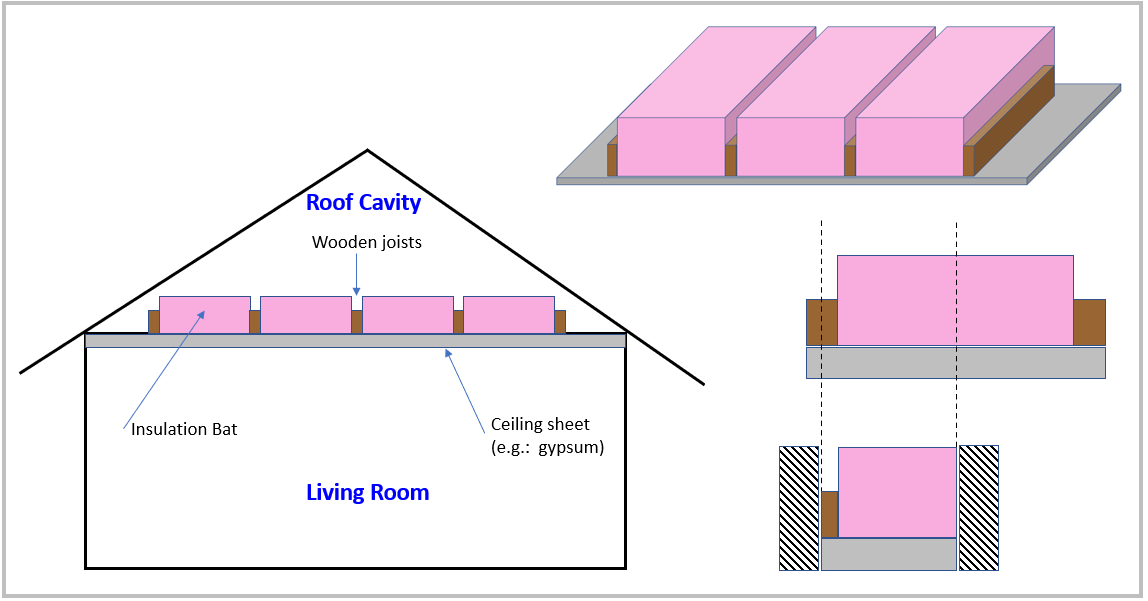

**History:**

- `19-Jul-2021: Created (bhorton@mathworks.com)`

## Problem Description:

We'll implement a first principles **Finite Difference** approach to solve a 2D Thermal Analysis problem.   **Finite Difference stencils** are computed based on an energy balance(conduction and convection) for a control surface around each different node type(see specifically [`bh_get_node_stencils`](matlab: edit bh_get_node_stencils)), eg:

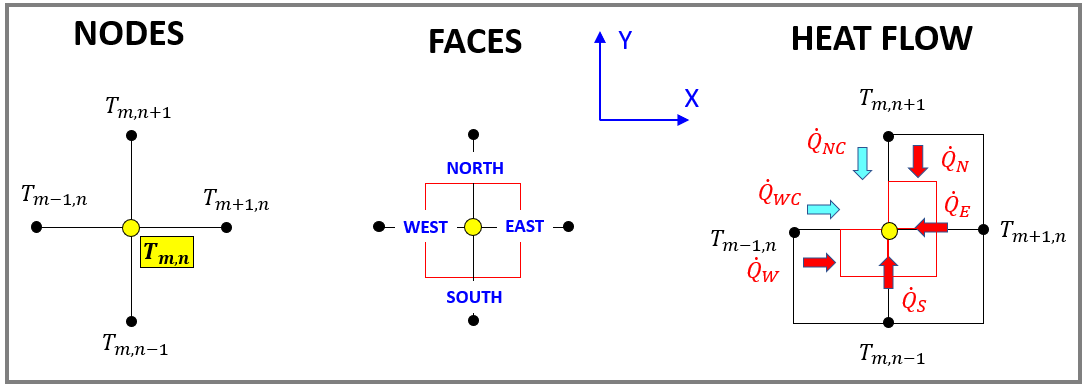

This script presents the Steady state thermal analysis of an insulation system installed in the roof cavity of a domestic house.  The system being considered is shown in the figure below - NOTE Point $\mathit{\mathbf{O}}$ is the "origin" for our spatial domain.  Key components of the system include:

- Block **A** :    a **Ceiling** sheet

- Block **B** :    a **Joist**

- Block **C** :    a Thermal insulation **Batt**

**System Boundary Conditions**

- Conduction in the X-direction through the EAST face of the  **Batt** is ZERO (a **symmetry condition**)

- Conduction in the X-direction through the WEST face of the  **Joist** is ZERO (a **symmetry condition**)

- Convection is possible in the Roof cavity (**Joist, Batt**)

- Convection is possible in the Living space (**Ceiling**)

**Co-ordinates and Node Labelling convention:**

- Point $\mathit{\mathbf{O}}$ is the "origin" for our spatial domain

- ${\textrm{NODE}}_{\;i\;,j}$ has a spatial co-ordinate of $\left(i\ldotp \Delta x\;,j\ldotp \Delta y\right)$

- ${\textrm{NODE}}_{\;i\;,j}$ has a Temperature of $T_{\;i\;,j}$

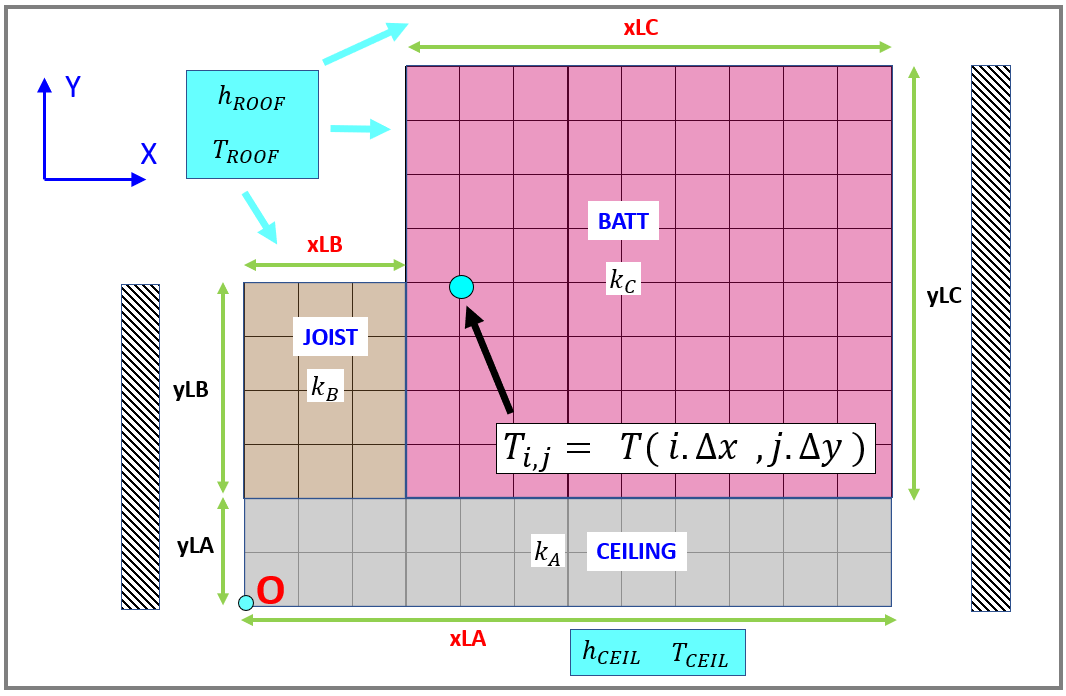

## **Load the **Labelled NODE table

The nodes used for this analysis have been entered into an EXCEL spreadsheet [**bh_NODE_table_dx_0p003.xlsx**](matlab: winopen(pwd  + string(filesep) + "bh_NODE_table_dx_0p003.xlsx")). 

 **ATTENTION:** 

- the data in this file corresponds to the case where $\Delta x\;=\;\Delta y=0\ldotp 003\;\;\left(m\right)\;$ 

- The Node TYPE must be one of the 23 different types described in the file [`bh_get_node_stencils`](matlab: edit bh_get_node_stencils)`.`

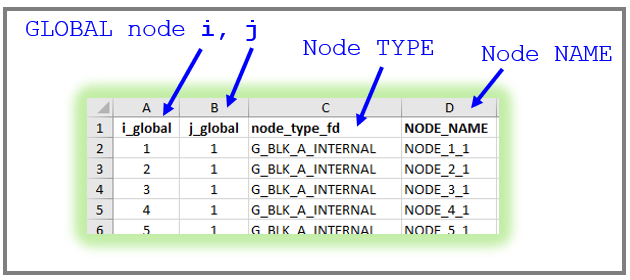

Read the Node GEOMETRY and the Node TYPE labels from the EXCEL file 

THE_EXCEL_FILENAME = "bh_NODE_table_dx_0p003.xlsx";

NODE_table = readtable(THE_EXCEL_FILENAME, "Sheet",     "NODE_SHEET", ...
                                           "TextType" , "string");
% allow the table ROW index to be the NODE_ID
NODE_table.Properties.RowNames = NODE_table.NODE_NAME;

head(NODE_table)

                i_global    j_global       node_type_fd       NODE_NAME 
                ________    ________    __________________    __________

    NODE_1_1       1           1        "G_BLK_A_INTERNAL"    "NODE_1_1"
    NODE_2_1       2           1        "G_BLK_A_INTERNAL"    "NODE_2_1"
    NODE_3_1       3           1        "G_BLK_A_INTERNAL"    "NODE_3_1"
    NODE_4_1       4           1        "G_BLK_A_INTERNAL"    "NODE_4_1"
    NODE_5_1       5           1        "G_BLK_A_INTERNAL"    "NODE_5_1"
    NODE_6_1       6           1        "G_BLK_A_INTERNAL"    "NODE_6_1"
    NODE_7_1       7           1        "G_BLK_A_INTERNAL"    "NODE_7_1"
    NODE_8_1       8           1        "G_BLK_A_INTERNAL"    "NODE_8_

Read the Finite Difference interval widths $\Delta x$ and $\Delta y$ 

dX_DY_table = readtable(THE_EXCEL_FILENAME, "Sheet", "DX_DY_SHEET")

dX_DY_table = 1×2 table
     DX       DY  
    _____    _____

    0.003    0.003


Lastly, construct a list of names for the Temperatures at each node

T_str_list = "T_" + NODE_table.i_global + "_" + NODE_table.j_global;

Here's a peak at a few of the names:

T_str_list(1:5)

ans = 5×1 string array
    "T_1_1"
    "T_2_1"
    "T_3_1"
    "T_4_1"
    "T_5_1"


## **Visualize the node geometry**

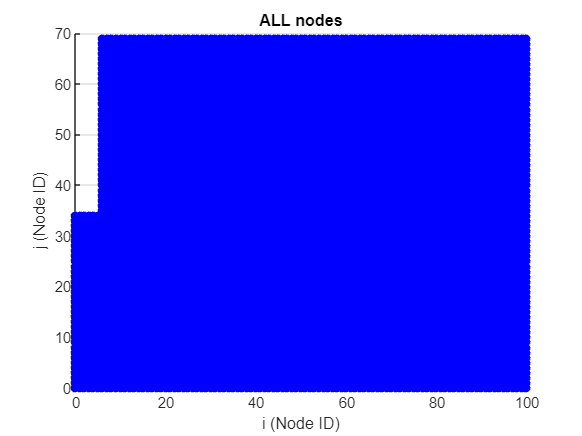

figure;
    scatter(NODE_table.i_global, NODE_table.j_global, [], "blue", "filled")
        xlabel('i (Node ID)'); ylabel('j (Node ID)'); 
        grid('On')
        title("ALL nodes")

And we can visualize the different **Node types** too:

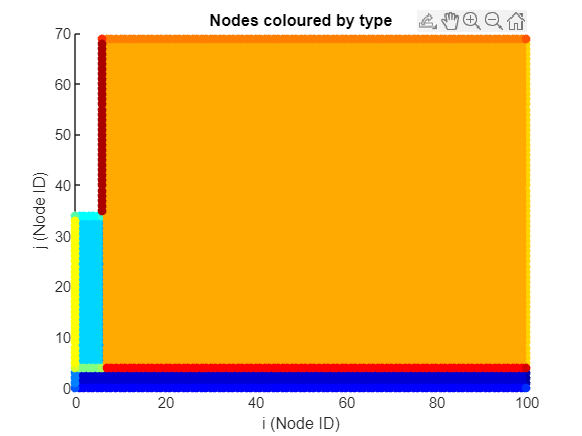

LOC_plot_nodes(NODE_table);        

## **Load Thermal and Geometric parameters**

Thermal and geometry parameters for this system are defined in an EXCEL file [**bh_PARAMS_DATABASE.xlsx**](matlab: winopen(pwd  + string(filesep) + "bh_PARAMS_DATABASE.xlsx")).  So let's read this data in.

- **NOTE**:  The physical widths of the BATT and JOIST as expressed in the EXCEL file ... are halved when they are assigned to our geometry fields **xLB, xLC ...** because our thermal analysis applies symmetry boundary conditions at the joist and batt.

OBJ_params = bh_sys_params_CLS("bh_PARAMS_DATABASE.xlsx", "SET_1")

OBJ_params =   bh_sys_params_CLS with properties:

     Filename: "bh_PARAMS_DATABASE.xlsx"
    Sheetname: "SET_1"
       my_tab: [19×5 table]
          k_A: 0.1700
          k_B: 0.1200
          k_C: 0.0488
       h_ROOF: 4
       h_CEIL: 1.3000
       T_ROOF: 55
       T_CEIL: 25
          xLA: 0.3000
          xLB: 0.0175
          xLC: 0.2825
          yLA: 0.0130
          yLB: 0.0900
          yLC: 0.1950
         Nx_A: []
         Nx_B: []
         Nx_C: []
         Ny_A: []
         Ny_B: []
         Ny_C: []
      Delta_X: []
      Delta_Y: []


Set the Finite Difference interval widths $\Delta x$ and $\Delta y$ 

my_dx      = dX_DY_table.DX;
my_dy      = dX_DY_table.DY;
OBJ_params = OBJ_params.set_deltas(my_dx, my_dy)

--------------------------------------------------
 TESTING discretization on component lengths 
--------------------------------------------------
 ... xLA diff =  0.0000 (m), [ 0.3000 --->  0.3000]
 ... xLB diff =  0.0005 (m), [ 0.0175 --->  0.0180]
 ... xLC diff =  0.0005 (m), [ 0.2825 --->  0.2820]
 ... yLA diff =  0.0010 (m), [ 0.0130 --->  0.0120]
 ... yLB diff =  0.0000 (m), [ 0.0900 --->  0.0900]
 ... yLC diff =  0.0000 (m), [ 0.1950 --->  0.1950]
--------------------------------------------------


OBJ_params =   bh_sys_params_CLS with properties:

     Filename: "bh_PARAMS_DATABASE.xlsx"
    Sheetname: "SET_1"
       my_tab: [19×5 table]
          k_A: 0.1700
          k_B: 0.1200
          k_C: 0.0488
       h_ROOF: 4
       h_CEIL: 1.3000
       T_ROOF: 55
       T_CEIL: 25
          xLA: 0.3000
          xLB: 0.0175
          xLC: 0.2825
          yLA: 0.0130
          yLB: 0.0900
          yLC: 0.1950
         Nx_A: 100
         Nx_B: 6
         Nx_C: 94
         Ny_A: 4
         Ny_B: 30
         Ny_C: 65
      Delta_X: 0.0030
      Delta_Y: 0.0030


## Compute the Finite Difference STENCILS for the different NODE types

For our specific problem there are ***23 different NODE types***.  For example see below.  The labels for these different node types are defined in the file [`bh_fd_node_type_ENUM.m`](matlab:  edit bh_fd_node_type_ENUM.m).  The function [`bh_get_node_stencils`](matlab: edit bh_get_node_stencils) does a STEADY STATE thermal analysis for each of these different node types. 

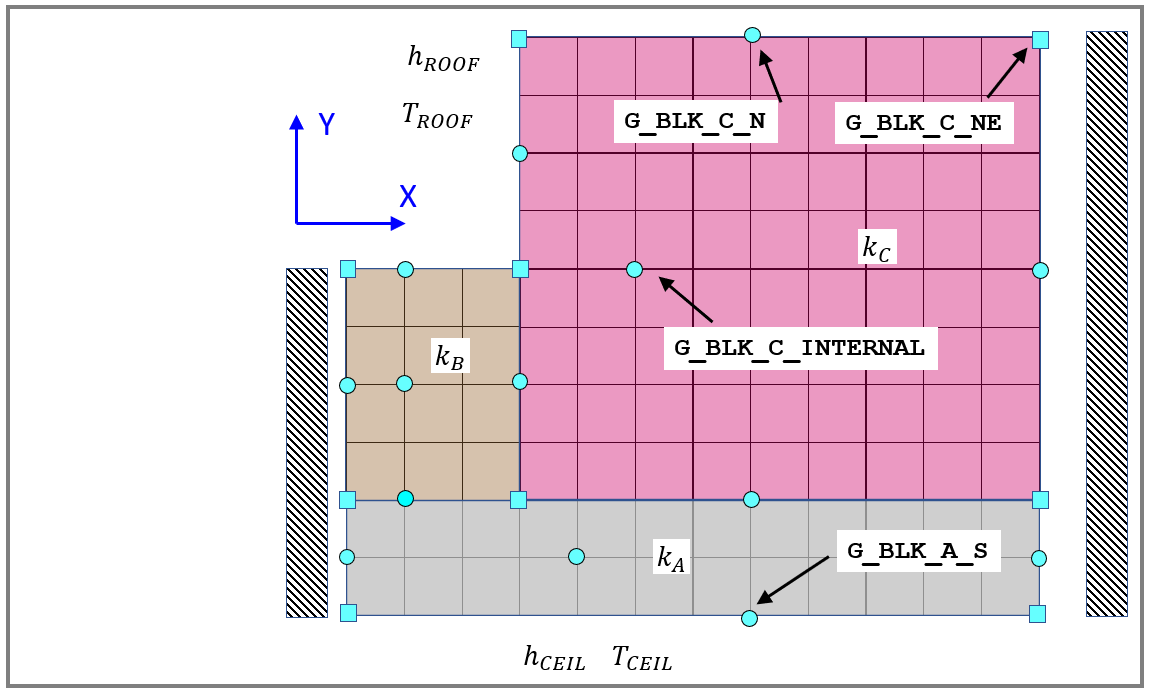

STENCIL_table = bh_get_node_stencils(OBJ_params)


 ... Finished [ 1] of 23 :  NODE_TYPE = G_BLK_B_INTERNAL
 ... Finished [ 2] of 23 :  NODE_TYPE = G_BLK_B_NW
 ... Finished [ 3] of 23 :  NODE_TYPE = G_BLK_B_N
 ... Finished [ 4] of 23 :  NODE_TYPE = G_BLK_B_NE
 ... Finished [ 5] of 23 :  NODE_TYPE = G_BLK_B_E
 ... Finished [ 6] of 23 :  NODE_TYPE = G_BLK_B_SE
 ... Finished [ 7] of 23 :  NODE_TYPE = G_BLK_B_S
 ... Finished [ 8] of 23 :  NODE_TYPE = G_BLK_B_SW
 ... Finished [ 9] of 23 :  NODE_TYPE = G_BLK_B_W
 ... Finished [10] of 23 :  NODE_TYPE = G_BLK_C_INTERNAL
 ... Finished [11] of 23 :  NODE_TYPE = G_BLK_C_W
 ... Finished [12] of 23 :  NODE_TYPE = G_BLK_C_NW
 ... Finished [13] of 23 :  NODE_TYPE = G_BLK_C_N
 ... Finished [14] of 23 :  NODE_TYPE = G_BLK_C_NE
 ... Finished [15] of 23 :  NODE_TYPE = G_BLK_C_E
 ... Finished [16] of 23 :  NODE_TYPE = G_BLK_C_SE
 ... Finished [17] of 23 :  NODE_TYPE = G_BLK_C_S
 ... Finished [18] of 23 :  NODE_TYPE = G_BLK_A_INTERNAL
 ... Finished [19] of 23 :  NODE_TYPE = G_BLK_A_SW
 ... Finished [20] o

STENCIL_table = 23×15 table
                           node_type_fd                                                                                                                                      s_A                                                                                                                                                              s_b                                                                                  s_x                                                                                                                  str_x                                                               T_mM1_nP1     T_m_nP1     T_mP1_nP1     T_mM1_n      T_m_n      T_mP1_n     T_mM1_nM1     T_m_nM1     T_mP1_nM1     b

**ATTENTION:**  In the next section we'll summarise the meaning of the entries in this STENCIL table ... but a more detailed discussion can also be found in the script file [`bh_CONCEPT_stencil`](matlab:  edit bh_CONCEPT_stencil) . 

## Pause and Ponder - the significance of the `STENCIL_table`

**NOTE**:  The STENCIL table has been designed so that you can use the node type as a mechanism to access the rows of the table

STENCIL_table("G_BLK_C_INTERNAL", :)

ans = 1×15 table
                           node_type_fd                                                                                              s_A                                                                                            s_b                                                        s_x                                                                                                                  str_x                                                               T_mM1_nP1    T_m_nP1     T_mP1_nP1    T_mM1_n     T_m_n    T_mP1_n     T_mM1_nM1    T_m_nM1     T_mP1_nM1    b
                        __________________    __________________________________________________________________________

For example the node type **G_BLK_C_INTERNAL** corresponds to an internal node within the insulation BATT.  The Control volume for this **specific** node is shown below:

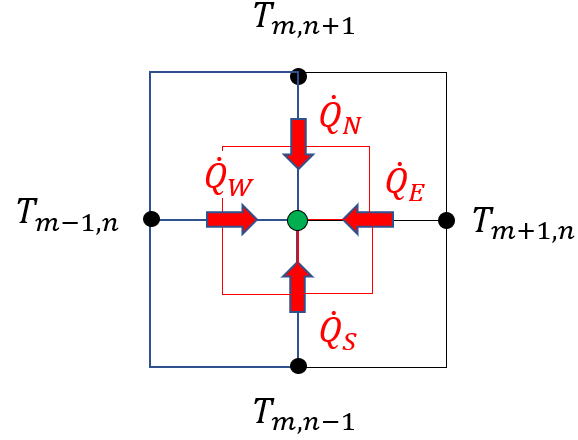                     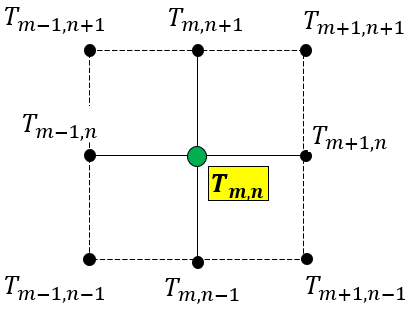

For the node type **G_BLK_C_INTERNAL**  we can write the Steady state Finite Difference stencil (see the function [`bh_get_node_stencils`](matlab: edit bh_get_node_stencils))  in the form:

- $A_{\textrm{NODE}} \;\ldotp z=b$          where        $z^T =\left\lbrack \begin{array}{ccccccccc}
T_{m-1,n+1}  & T_{m,n+1}  & T_{m+1,n+1}  & T_{m-1,n}  & T_{m,n}  & T_{m+1,n}  & T_{m-1,n-1}  & T_{m,n-1}  & T_{m+1,n-1} 
\end{array}\right\rbrack$

Symbolically, the $A_{\textrm{NODE}}$ and $b$ matrices for the **G_BLK_C_INTERNAL** node, are:

STENCIL_table{"G_BLK_C_INTERNAL", "s_A"}{1}

$$ans = \left(\begin{array}{ccccccccc} 0 & -\frac{\Delta_{X}\,k_{C}}{\Delta_{Y}} & 0 & -\frac{\Delta_{Y}\,k_{C}}{\Delta_{X}} & \frac{2\,\Delta_{X}\,k_{C}}{\Delta_{Y}}+\frac{2\,\Delta_{Y}\,k_{C}}{\Delta_{X}} & -\frac{\Delta_{Y}\,k_{C}}{\Delta_{X}} & 0 & -\frac{\Delta_{X}\,k_{C}}{\Delta_{Y}} & 0 \end{array}\right)$$

STENCIL_table{"G_BLK_C_INTERNAL", "s_b"}{1}

$$ans = \left(\begin{array}{c} 0 \end{array}\right)$$

Numerically, the $A_{\textrm{NODE}}$ and $b$ matrices for the **G_BLK_C_INTERNAL** node, are:

STENCIL_table{"G_BLK_C_INTERNAL", ["T_mM1_nP1","T_m_nP1","T_mP1_nP1","T_mM1_n","T_m_n","T_mP1_n","T_mM1_nM1","T_m_nM1","T_mP1_nM1"]}

ans =          0   -0.0488         0   -0.0488    0.1950   -0.0488         0   -0.0488         0


STENCIL_table{"G_BLK_C_INTERNAL", "b"}

ans = 0

Similarly, consider the node type **G_BLK_B_N**  - a node on the north face of the joist

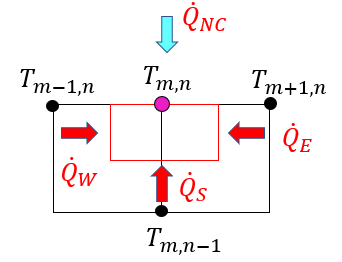              

Symbolically, the $A_{\textrm{NODE}}$ and $b$ matrices for the **G_BLK_C_INTERNAL** node, are:

STENCIL_table{"G_BLK_B_N", "s_A"}{1}

$$ans = \left(\begin{array}{ccccccccc} 0 & 0 & 0 & -\frac{\Delta_{Y}\,k_{B}}{2\,\Delta_{X}} & \Delta_{X}\,h_{\mathrm{ROOF}}+\frac{\Delta_{X}\,k_{B}}{\Delta_{Y}}+\frac{\Delta_{Y}\,k_{B}}{\Delta_{X}} & -\frac{\Delta_{Y}\,k_{B}}{2\,\Delta_{X}} & 0 & -\frac{\Delta_{X}\,k_{B}}{\Delta_{Y}} & 0 \end{array}\right)$$

STENCIL_table{"G_BLK_B_N", "s_b"}{1}

$$ans = \left(\begin{array}{c} \Delta_{X}\,T_{\mathrm{ROOF}}\,h_{\mathrm{ROOF}} \end{array}\right)$$

Numerically, the $A_{\textrm{NODE}}$ and $b$ matrices for the **G_BLK_C_INTERNAL** node, are:

STENCIL_table{"G_BLK_B_N", ["T_mM1_nP1","T_m_nP1","T_mP1_nP1","T_mM1_n","T_m_n","T_mP1_n","T_mM1_nM1","T_m_nM1","T_mP1_nM1"]}

ans =          0         0         0   -0.0600    0.2520   -0.0600         0   -0.1200         0


STENCIL_table{"G_BLK_B_N", "b"}

ans = 0.6600

## Assemble the system `A.x=b` equations

Now we can assemble the SYSTEM $A\;\textrm{and}\;b$ matrices for the entire system.  For each node in our NODE table, we do the following:

- get it's node type

- retrieve the finite difference stencil for that particular node type

- determine the columns of the GLOBAL $A$ matrix to populate

- NOTE:  the global $A$ matrix is a **SPARSE matrix**, ie: most elements in the matrix are ZEROS

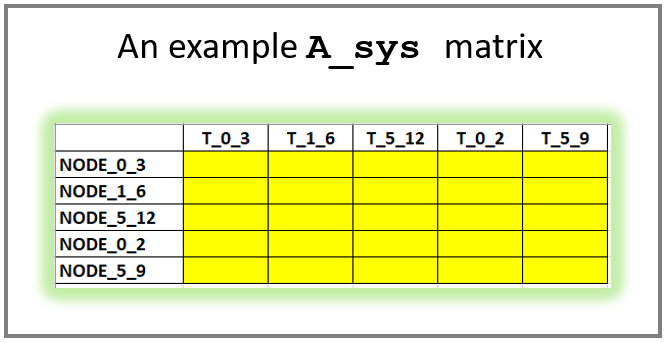

NUM_NODES = height(NODE_table);

A_sys     = sparse(NUM_NODES, NUM_NODES);
b_sys     = sparse(NUM_NODES, 1);

for kk=1:NUM_NODES  
    
      m             = NODE_table.i_global(kk);
      n             = NODE_table.j_global(kk);
      node_type_str = NODE_table.node_type_fd(kk);
      
      % Get the STENCIL for this node type 
      %  - SEE the SUBfunction at the bottom of this script
      [A, b, x_str] = LOCAL_retrieve_Abx(STENCIL_table, node_type_str, m, n);
      
      % Now for each node in the STENCIL, find the corresponding COLUMN in
      % our system A matrix and insert the co-efficient value
      ia = zeros(size(x_str));
      for ii=1:length(x_str)
         ia(ii) = find(T_str_list == x_str(ii) );
      end % for ii
      
      A_sys(kk, ia) = A(1,:);
      b_sys(kk)     = b;
      
      if(0==mod(kk,1000))
          fprintf('\n ... completed kk=%6d of %d',kk,NUM_NODES);
      end
      
end % for kk=1:NUM_NODES


 ... completed kk=  1000 of 6860
 ... completed kk=  2000 of 6860
 ... completed kk=  3000 of 6860
 ... completed kk=  4000 of 6860
 ... completed kk=  5000 of 6860
 ... completed kk=  6000 of 6860

## Solve the system `A.x=b` equations

So our GLOBAL system  $A$ and $b$ matrices have now been populated.

 How big are they ?

whos A_sys  b_sys

  Name          Size               Bytes  Class     Attributes

  A_sys      6860x6860            598216  double    sparse    
  b_sys      6860x1                 3872  double    sparse    



**NOTE**:  because we created these matrices as **SPARSE** matrices, they do NOT consume much memory on your laptop.  Have a look at exactly how "sparse" our `A_sys` matrix really is - the BLUE dots correspond to positions storing NON zero values ... and WHITE represents locations where a ZERO would be

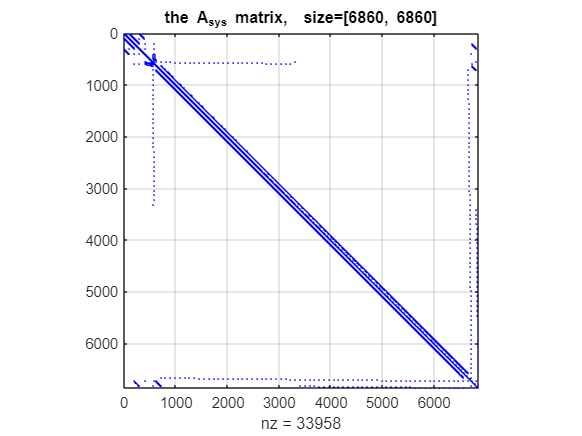

figure;
    spy(A_sys, '.b');
            tmp_str = sprintf("the A_{sys} matrix,  size=[%d, %d]", size(A_sys,1), size(A_sys,2) );
        title(tmp_str);
        grid("on")

OK, now we can solve our GLOBAL system of equations, ie:  $A\ldotp x=b\;\;\;\;\;\Longrightarrow \;\;\;\;\;x=A\backslash b$ . 

x_sys = A_sys \ b_sys;

## And Visualize the results

Visualize the Steady state temperature values across our mesh

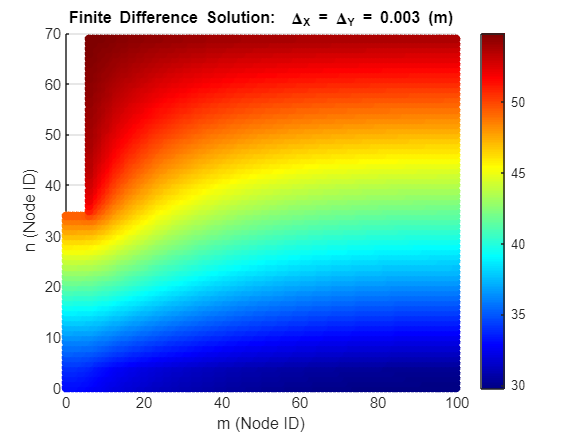

figure;
    scatter3(NODE_table.i_global, NODE_table.j_global, x_sys, [], x_sys, "filled")
        xlabel('m (Node ID)'); ylabel('n (Node ID)'); 
        grid('On')
        title("Finite Difference Solution:  \Delta_X = \Delta_Y = "+ my_dx + " (m)")
        colormap(jet(200))            
        colorbar;
        view(2)

## Now compute the Heat flow rate flowing through the ceiling boundary

For each ceiling node on the SOUTH boundary of the ceiling block we have

- $\frac{{\dot{Q} }_{\textrm{SC}} }{L_Z }\;=\;h_{\textrm{CEIL}} \;\;\ldotp \bar{A} \;\ldotp \left(T_{\textrm{CEIL}} -T_{m\ldotp n} \right)$       where    $\bar{A\;} \;=\;\frac{A}{L_Z }$   and $L_Z$ is the $Z$ axis length

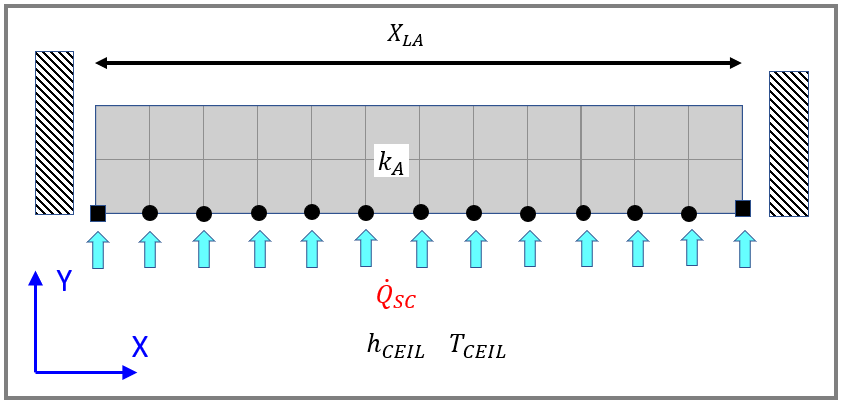

 Let's create a NEW table and add a column called `T_ss `that contains our steady state Temperature solution

my_tab      = NODE_table;
my_tab.T_ss = x_sys;

Now extract rows from the mesh table that correspond to the ceiling SOUTH face boundary:

tf_ind        = my_tab.node_type_fd == "G_BLK_A_SW";
SW_corner_tab = my_tab(tf_ind,:);

tf_ind        = my_tab.node_type_fd == "G_BLK_A_SE";
SE_corner_tab = my_tab(tf_ind,:);

tf_ind        = my_tab.node_type_fd == "G_BLK_A_S";
S_face_tab    = my_tab(tf_ind,:);

mini_tab      = [SW_corner_tab;
                 SE_corner_tab;
                 S_face_tab ];

OK, let's accumulate the heat flowrate through the south face of each node:

- 
$$\frac{{\dot{Q} }_{\textrm{SC}} }{L_Z }\;\;=\;\;\sum_m \;\;h_{\textrm{CEIL}} \;\;\ldotp \bar{A} \;\ldotp \left(T_{\textrm{CEIL}} -T_{m\ldotp n} \right)\;\;$$


Q_norm = 0;
for kk =1:height(mini_tab)
    node_type = mini_tab.node_type_fd(kk);
    switch(node_type)
        case {"G_BLK_A_SW","G_BLK_A_SE"}
              Area = OBJ_params.Delta_X/2;
        case "G_BLK_A_S"
              Area = OBJ_params.Delta_X;
        otherwise
            error("###_ERROR: This should NOT happen !");
    end
    
    Q_norm = Q_norm +  (OBJ_params.h_CEIL * Area * (OBJ_params.T_CEIL - mini_tab.T_ss(kk)));
    
end

And the answer is:

display(Q_norm)

Q_norm = -2.2097

So this represents the heat flowrate per unit $L_Z$ for a length of ceiling $X_{\textrm{LA}}$

## What is the Heat flowrate into the Living Room ?

Say we have a Living room that has a ceiling with the following dimensions:

X_ROOM = 5;  % (m)
Z_ROOM = 4;  % (m)

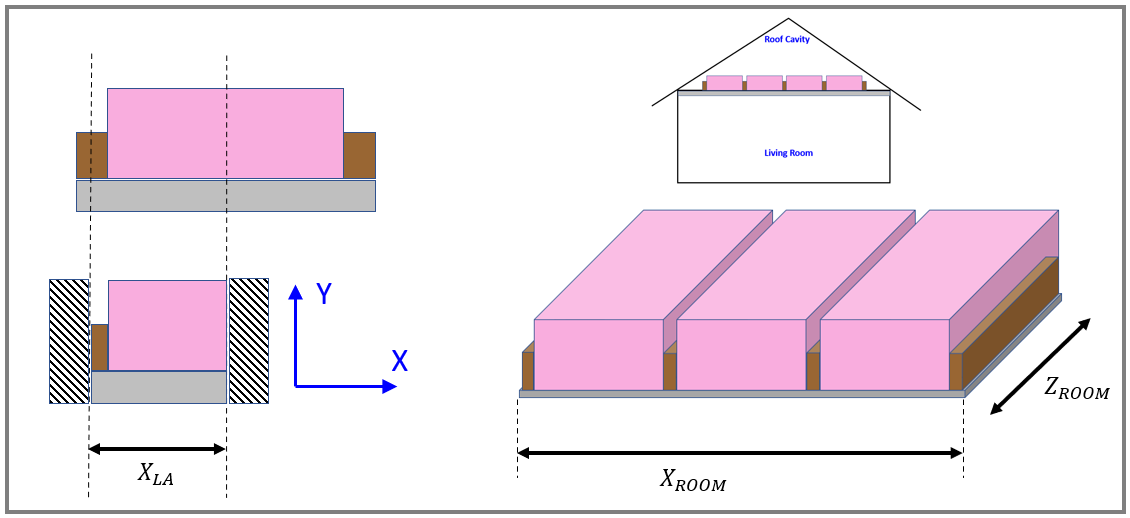

What is the heat flowrate $\left(\textrm{Watts}\right)$ being pumped into this room ?

Q_room = Q_norm * Z_ROOM * (X_ROOM / OBJ_params.xLA)

Q_room = -147.3100

# Local **Subfunctions** only beyond this point

function [A, b, x_str] = LOCAL_retrieve_Abx(STENCIL_table, node_str, m, n)
    arguments 
       STENCIL_table       table 
       node_str      (1,1) string
       m             (1,1) double
       n             (1,1) double
    end
    
    the_row    = STENCIL_table(node_str,:);   
    
    T_str_list = the_row{1,"str_x"}{1};
    A_num      = the_row{1, T_str_list};
    
    % Dismiss columns with ZERO values
    tf_ZERO_COLS = A_num == 0;

    T_str_list(tf_ZERO_COLS)  = [];
    A_num(tf_ZERO_COLS)       = [];
    % Produce the list with tokens replaced by the values for m and n
    res_str_list = strings(1, length(T_str_list) );

     for kk=1:length(T_str_list)

            THE_STR = T_str_list(kk);

            switch(THE_STR)
                case "T_mM1_nP1" 
                                 res_str_list(kk) = "T_" + (m-1) + "_" + (n+1);
                case "T_m_nP1" 
                                 res_str_list(kk) = "T_" + (m) + "_"   + (n+1);
                case "T_mP1_nP1"
                                 res_str_list(kk) = "T_" + (m+1) + "_" + (n+1);
                case "T_mM1_n"  
                                 res_str_list(kk) = "T_" + (m-1) + "_" + (n); 
                case "T_m_n" 
                                 res_str_list(kk) = "T_" + (m) + "_"   + (n);
                case "T_mP1_n"
                                 res_str_list(kk) = "T_" + (m+1) + "_" + (n); 
                case "T_mM1_nM1"
                                 res_str_list(kk) = "T_" + (m-1) + "_" + (n-1);
                case "T_m_nM1" 
                                 res_str_list(kk) = "T_" + (m) + "_"   + (n-1);
                case "T_mP1_nM1" 
                                 res_str_list(kk) = "T_" + (m+1) + "_" + (n-1); 
                otherwise
                    error("###_ERROR:  Bad ! ")
            end            
     end % for kk=1:length(new_str_list)
     
     % take care of the outputs
     A     = A_num;
     b     = the_row.b;
     x_str = res_str_list;
     
     % do a quick bit of checking
     assert(length(x_str) > 0, "###_ERROR:  bad !")
     
end % function retrieve  

A node visualization function

function LOC_plot_nodes(NODE_table)
     
    unq_node_types = string(  unique(NODE_table.node_type_fd)  );
    N_nd_types     = length(unq_node_types);    
    my_colr_map    = jet(N_nd_types);
    
    figure;
    
    for kk=1:N_nd_types
    
        tf_list    =   string(NODE_table.node_type_fd) == unq_node_types(kk);
        my_x       =  NODE_table.i_global(tf_list);
        my_y       =  NODE_table.j_global(tf_list);        
        my_colr    = my_colr_map(kk,:);

        scatter(my_x, my_y, [], my_colr, "filled"); 
        hold(gca,"on")
    end
    xlabel('i (Node ID)'); ylabel('j (Node ID)');
    title("Nodes coloured by type")
end